I1 = checkerboard(10,40,10)>.1;
I2 = checkerboard(10,10,20)>.1;
I3 = checkerboard(10,10,10)>.1;
I = {I1 I2 I3}

I = 1×3 cell array
    {800×200 logical}    {200×400 logical}    {200×200 logical}


msb =2

msb = 2

nsb =  3

nsb = 3

p =0

p = 0

p = 1

sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


p = 2

sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


p = 3

sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


p = 4

sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


p = 5

sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


p = 6

sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


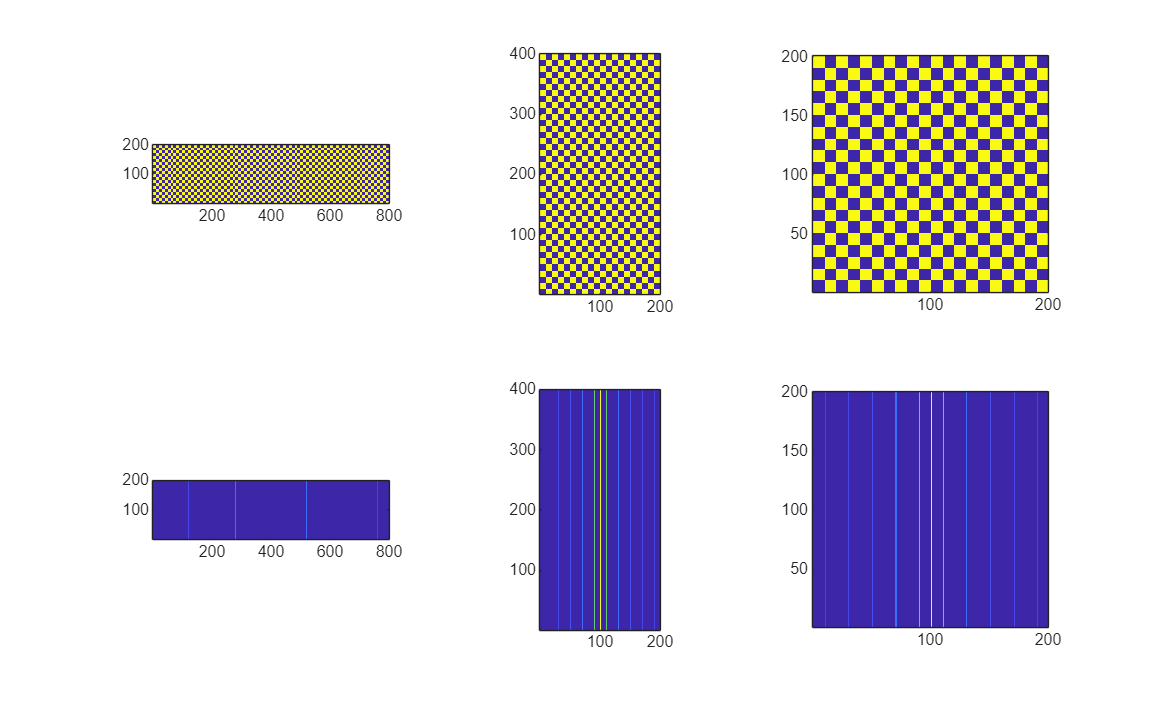

for isb = 1:msb
    for jsb = 1:nsb
        p = p+ 1
        sbs(isb,jsb) = subplot(msb,nsb,p)
        if isb == 1
            views(I{jsb})
        elseif isb == 2
            views(fftshift(abs(fft(I{jsb}))))

        end
    end
end